% I. Setup

clc;
clear all;
close all;

addpath_recurse(pwd);

% II. Load data

load HU2013.mat;
HSI = HU2013;
load TRLabel
load TSLabel
Tr = TRLabel;
Te = TSLabel;
clear TRLabel TSLabel HU2013
classes_label = ["Healthy grass","Stressed grass","Synthetic grass","Trees","Soil","Water","Residential","Commercial","Road","Highway","Railway","Parking Lot 1","Parking Lot 2","Tennis Court","Running Track"];

% Load saved data
files_list = dir('Saved_Data\*.mat');
for i = 1:length(files_list);
    load(files_list(i).name);
end

% Global parameters
dim = 15; % 15 classes for the Houston dataset
Trees = 50; % for RF training
[nx,ny,nz] = size(HSI);

% III. PCA / OTVCA

% Computation

HSI_2D = DataNormlization(reshape(HSI,nx*ny,nz));
[COEFF, FE_PCA] = pca(HSI_2D, "Algorithm", "svd", "NumComponents", dim);
FE_PCA = reshape(FE_PCA(:,1:dim),[nx ny dim]);

FE_OTVCA = OTVCA_V3(HSI, dim, 0.01, Trees);

1	2	3	4	5	6	7	8	9	10	11	12	13	14	15	16	17	18	19	20	21	22	23	24	25	26	27	28	29	30	31	32	33	34	35	36	37	38	39	40	41	42	43	44	45	46	47	48	49	50	


save('Saved_Data/FE_PCA.mat','FE_PCA');
save('Saved_Data/FE_OTVCA.mat','FE_OTVCA');

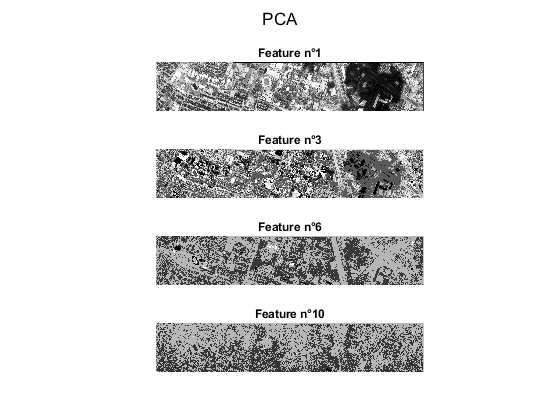

% Comparison

Norm_FE_PCA = rescale(FE_PCA);
Norm_FE_OTVCA = 1-rescale(FE_OTVCA);
features_num = [1 3 6 10];
features_comparison(Norm_FE_PCA, "PCA", features_num);

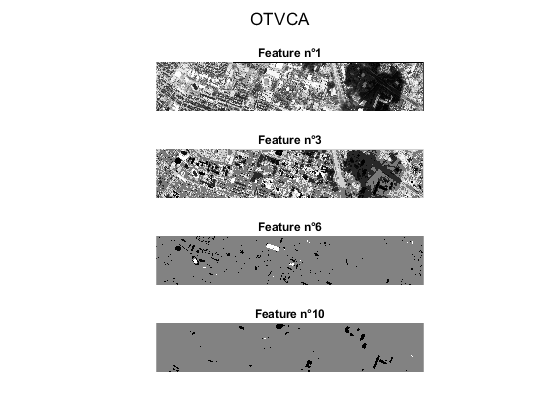

features_comparison(Norm_FE_OTVCA, "OTVCA", features_num);

% IV. LDA / Jplay

% Computation

HSI2d = hyperConvert2d(HSI);

TrainI2d = hyperConvert2d(Tr);
TestI2d = hyperConvert2d(Te);

l_Tr = find(TrainI2d > 0);
l_Te = find(TestI2d > 0);

Samples_Tr_LDA = HSI2d(:, l_Tr);
Samples_Te_LDA = HSI2d(:, l_Te);
Labels_Tr_LDA = TrainI2d(:, l_Tr);
Labels_Te_LDA = TestI2d(:, l_Te);

[~, mapping_LDA] = lda(Samples_Tr_LDA', Labels_Tr_LDA', dim-1);
M_LDA = mapping_LDA.M;

fea_LDA = M_LDA' * [Samples_Tr_LDA, Samples_Te_LDA];
fea_all_LDA = M_LDA' * HSI2d;

train_fea_LDA = fea_LDA(:, 1 : length(Labels_Tr_LDA));
test_fea_LDA = fea_LDA(:, length(Labels_Tr_LDA)+1 : end);

HSI2d_Norm = DataNormlization(HSI2d);
Samples_Tr_JP = HSI2d_Norm(:, l_Tr);
Samples_Te_JP = HSI2d_Norm(:, l_Te);
Labels_Tr_JP = TrainI2d(:, l_Tr);
Labels_Te_JP = TestI2d(:, l_Te);

num = 10;
sigma = 0.1;
alfa = 1;
beta = 0.1;
gamma = 0.1;
rho = 2;
maxiter = 1000;
eta = 1;
epsilon = 1e-4;
k=100;
layer = 5;

[NewSamples_Tr, NewLabels_Tr] = ClusterCenter(Samples_Tr_JP, Labels_Tr_JP, k);

Replicate 1, 5 iterations, total sum of distances = 0.0028758.
Best total sum of distances = 0.0028758
Replicate 1, 5 iterations, total sum of distances = 0.0057711.
Best total sum of distances = 0.0057711
Replicate 1, 4 iterations, total sum of distances = 0.00566466.
Best total sum of distances = 0.00566466
Replicate 1, 6 iterations, total sum of distances = 0.00642969.
Best total sum of distances = 0.00642969
Replicate 1, 7 iterations, total sum of distances = 0.00253361.
Best total sum of distances = 0.00253361
Replicate 1, 6 iterations, total sum of distances = 0.00911718.
Best total sum of distances = 0.00911718
Replicate 1, 5 iterations, total sum of distances = 0.0103977.
Best total sum of distances = 0.0103977
Replicate 1, 8 iterations, total sum of distances = 0.00536209.
Best total sum of distances = 0.00536209
Replicate 1, 13 iterations, total sum of distances = 0.00413564.
Best total sum of distances = 0.00413564
Replicate 1, 7 iterations, total sum of distances = 0.002607

Y = GeneLableY(NewLabels_Tr, max(NewLabels_Tr));
[G, L] = creatLap(NewSamples_Tr, num, sigma);
d = generatePath(nz, layer, dim); 
[theta,P,res] = JPLAY(NewSamples_Tr,Y,G,L,k,d,sigma,alfa,beta,gamma,rho,maxiter,eta,epsilon);

 i = 11.000000,res_Obj= 0.000243
 i = 21.000000,res_Obj= 0.000145
 i = 31.000000,res_Obj= 0.000691
 i = 41.000000,res_Obj= 0.000654
 i = 48.000000,res_Obj= 0.000094


fea_JP = [Samples_Tr_JP, Samples_Te_JP];
fea_all_JP = HSI2d_Norm;
for i = 1 : length(d)
    fea_JP = theta{1, i} * fea_JP;
    fea_all_JP = theta{1, i} * fea_all_JP;
end

train_fea_JP = fea_JP(:, 1 : length(Labels_Tr_JP));
test_fea_JP = fea_JP(:, length(Labels_Tr_JP)+1 : end);

FE_LDA = reshape(fea_all_LDA,dim-1,nx,ny);
FE_JP = reshape(fea_all_JP,dim,nx,ny);

save('Saved_Data/FE_LDA.mat','FE_LDA');
save('Saved_Data/FE_JP.mat','FE_JP');

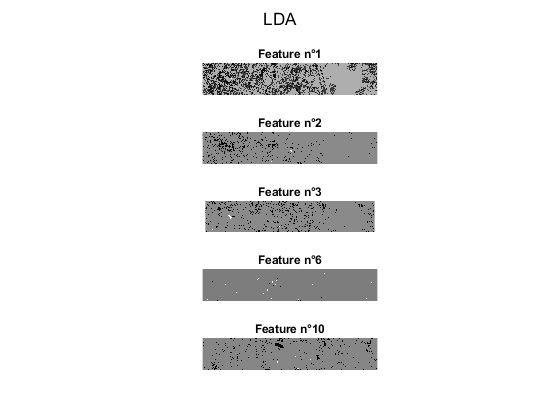

% Comparison

Norm_FE_LDA = rescale(permute(FE_LDA,[2 3 1]));
Norm_FE_JP = rescale(permute(FE_JP,[2 3 1]));
features_num = [1 2 3 6 10];
features_comparison(Norm_FE_LDA, "LDA", features_num);

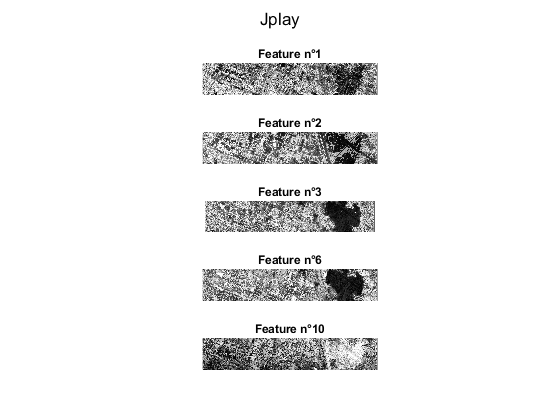

features_comparison(Norm_FE_JP, "Jplay", features_num);

% V. Random Forest classifier

% Computation

[acc_Mean_PCA,acc_std_PCA,CM_PCA,confu_PCA] = RF_ntimes_overal(FE_PCA,Tr,Te,Trees);

pa_PCA=acc_Mean_PCA(1:dim,1);
oa_PCA=acc_Mean_PCA(dim+2,1);
K_PCA=acc_Mean_PCA(dim+3,1);

[acc_Mean_OTVCA,acc_std_OTVCA,CM_OTVCA,confu_OTVCA] = RF_ntimes_overal(FE_OTVCA,Tr,Te,Trees);

pa_OTVCA=acc_Mean_OTVCA(1:dim,1);
oa_OTVCA=acc_Mean_OTVCA(dim+2,1);
K_OTVCA=acc_Mean_OTVCA(dim+3,1);

model_LDA = classRF_train(train_fea_LDA', Labels_Tr_LDA', Trees);

classTest_LDA = classRF_predict(test_fea_LDA', model_LDA);
[oa_LDA, ua_LDA, pa_LDA, K_LDA, confu_LDA]= confusion(Labels_Te_LDA', classTest_LDA);
classAll_LDA = classRF_predict(fea_all_LDA', model_LDA);
CM_LDA = hyperConvert3d(classAll_LDA,nx,ny);

model_JP = classRF_train(train_fea_JP', Labels_Tr_JP', Trees);

classTest_JP = classRF_predict(test_fea_JP', model_JP);
[oa_JP, ua_JP, pa_JP, K_JP, confu_JP]= confusion(Labels_Te_JP', classTest_JP);
classAll_JP = classRF_predict(fea_all_JP', model_JP);
CM_JP = hyperConvert3d(classAll_JP,nx,ny);

[acc_Mean_SP,acc_std_SP,CM_SP,confu_SP] = RF_ntimes_overal(HSI,Tr,Te,Trees);

pa_SP=acc_Mean_SP(1:dim,1);
oa_SP=acc_Mean_SP(dim+2,1);
K_SP=acc_Mean_SP(dim+3,1);

% Save results

save('Saved_Data/CM_PCA.mat','CM_PCA');
save('Saved_Data/CM_OTVCA.mat','CM_OTVCA');
save('Saved_Data/CM_LDA.mat','CM_LDA');
save('Saved_Data/CM_JP.mat','CM_JP');
save('Saved_Data/CM_SP.mat','CM_SP');

save('Saved_Data/confu_PCA.mat','confu_PCA');
save('Saved_Data/confu_OTVCA.mat','confu_OTVCA');
save('Saved_Data/confu_LDA.mat','confu_LDA');
save('Saved_Data/confu_JP.mat','confu_JP');
save('Saved_Data/confu_SP.mat','confu_SP');

oa = [oa_PCA, oa_OTVCA, oa_LDA, oa_JP, oa_SP];
pa = [pa_PCA, pa_OTVCA, pa_LDA, pa_JP, pa_SP];
aa = mean(pa,1);
K = [K_PCA, K_OTVCA, K_LDA, K_JP, K_SP];

save('Saved_Data/oa.mat','oa');
save('Saved_Data/pa.mat','pa');
save('Saved_Data/aa.mat','aa');
save('Saved_Data/K.mat','K');

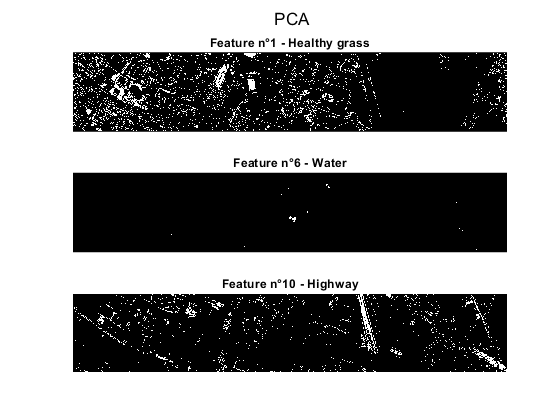

% VI. Visual comparison of the classes

classes_num = [1 6 10];
classes_comparison(CM_PCA, "PCA", classes_num, classes_label);

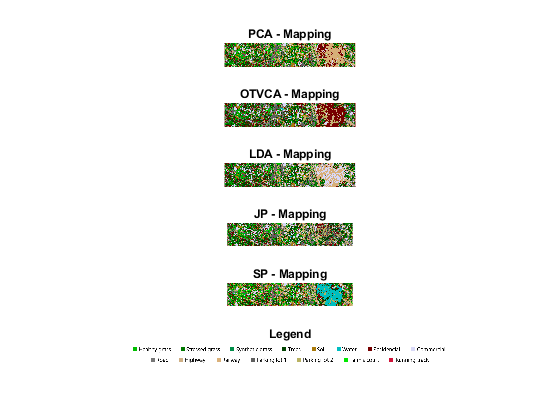

show_mapping(CM_PCA,"PCA", CM_OTVCA,"OTVCA",CM_LDA,"LDA",CM_JP,"JP",CM_SP,"SP");